AS_wavelengths = [410, 440, 470, 510, 550, 583, 620, 670];
VEML_wavelengths = [650, 550, 450];
b = 10;

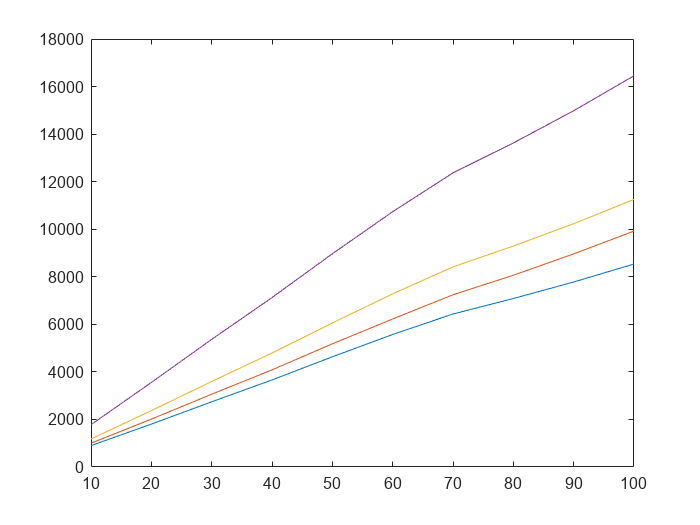

BLUE_Scaled = scale(BLUE);
[BLUE_10_AS, BLUE_10_VEML] = retrieve_int(BLUE_Scaled, b);
% boxplot(transpose(BLUE_10_AS(1:8,:)),AS_wavelengths);

% boxplot(transpose(BLUE_10_VEML(1:3,:)),VEML_wavelengths);


RED_Scaled = scale(RED);
[RED_10_AS, RED_10_VEML] = retrieve_int(RED_Scaled, b);
% boxplot(transpose(RED_10_AS(1:8,:)),AS_wavelengths);
% boxplot(transpose(RED_10_VEML(1:3,:)),VEML_wavelengths);


GREEN_Scaled = scale(GREEN);
[GREEN_10_AS, GREEN_10_VEML] = retrieve_int(GREEN_Scaled, b);
% boxplot(transpose(GREEN_10_AS(1:8,:)),AS_wavelengths);
% boxplot(transpose(GREEN_10_VEML(1:3,:)),VEML_wavelengths);

WHITE_Scaled = scale(WHITE);
[WHITE_10_AS, WHITE_10_VEML] = retrieve_int(WHITE_Scaled, b);
% boxplot(transpose(WHITE_10_AS(1:8,:)),AS_wavelengths);
% boxplot(transpose(WHITE_10_VEML(1:3,:)),VEML_wavelengths);

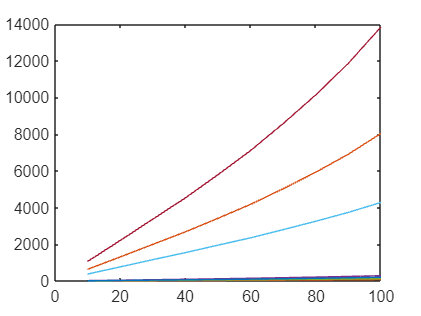

% Brightness vs counts plots for specific integration time
int = dictionary([40, 80, 160, 320, 640, 1280],1:6);
integration_time = 320;
[RED_Brightness_160_AS, RED_Brightness_160_VEML] = retrieve_brightness(RED_Scaled, int(integration_time));
plot(10:10:100, RED_Brightness_160_AS);

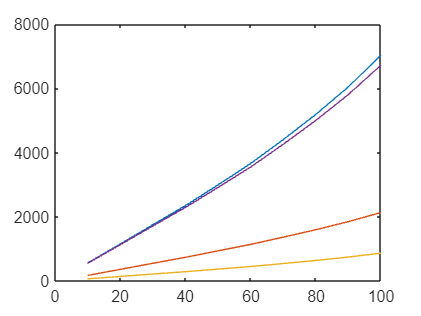


plot(10:10:100, RED_Brightness_160_VEML);

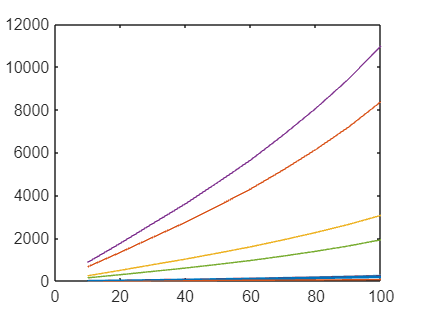


[GREEN_Brightness_160_AS, GREEN_Brightness_160_VEML] = retrieve_brightness(GREEN_Scaled, int(integration_time));
plot(10:10:100, GREEN_Brightness_160_AS);

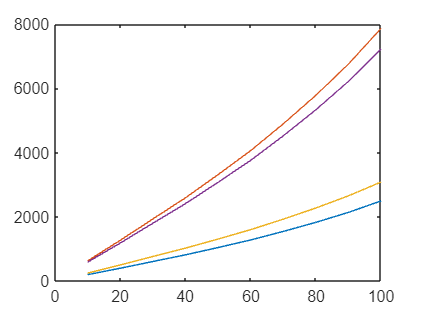

plot(10:10:100, GREEN_Brightness_160_VEML);

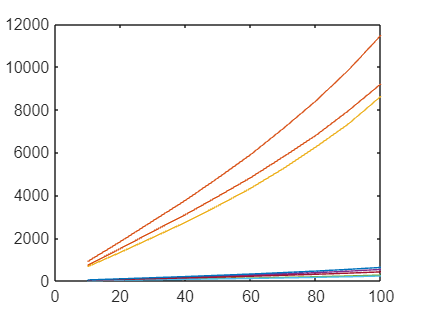


[BLUE_Brightness_160_AS, BLUE_Brightness_160_VEML] = retrieve_brightness(BLUE_Scaled, int(integration_time));
plot(10:10:100, BLUE_Brightness_160_AS);

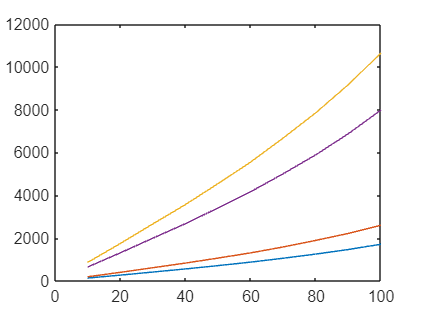

plot(10:10:100, BLUE_Brightness_160_VEML);

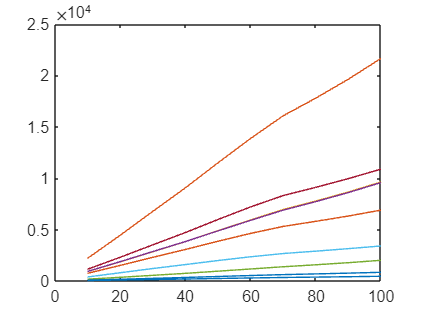


[WHITE_Brightness_160_AS, WHITE_Brightness_160_VEML] = retrieve_brightness(WHITE_Scaled, int(integration_time));
plot(10:10:100, WHITE_Brightness_160_AS);

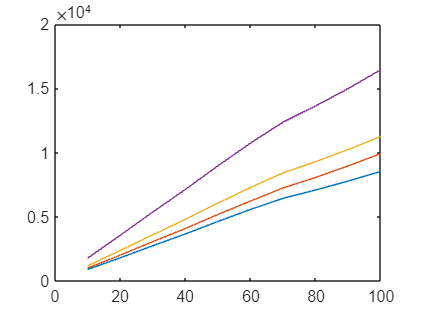

plot(10:10:100, WHITE_Brightness_160_VEML);

WHITE_160 = cell2mat(WHITE(:,3));
WHITE_160./WHITE_160(1,:)

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    2.0000    2.0336    2.0081    2.0174    1.9947    2.0624    2.0155    2.0120    2.0190    1.9846    2.0132    2.0145    2.0134    2.0018    1.0000
    3.0447    3.0905    3.0647    3.0740    3.0547    3.1229    3.0724    3.0778    3.0744    3.0438    3.0619    3.0654    3.0566    3.0240    1.0000
    4.0979    4.1167    4.1222    4.1182    4.1266    4.1201    4.1177    4.1335    4.1150    4.1372    4.0907    4.0929    4.0755    4.0153    1.0000
    5.2128    5.1916    5.2652    5.2349    5.3041    5.1306    5.2268    5.2707    5.2204    5.3297    5.1774    5.1872    5.1511    5.0527    1.0000
    6.2840    6.2173    6.3969    6.3364    6.4924    6.0759    6.2989    6.3952    6.2969    6.5072    6.2273    6.2322    6.1905    6.0506    1.0000
    7.2989    7.1417    7.4996    7.4106    7.7081    6.8987    7.2787    7.4611    7.31

RED_160 = cell2mat(RED(:,3));
RED_160./RED_160(1,:)

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    2.0038    2.2000    2.0000    2.0197    2.0000    2.0423    2.0749    2.0136    2.0578    2.1211    2.0615    2.0760    2.0529    2.0571    1.0000
    3.0769    3.4000    3.0714    3.0965    3.1000    3.0865    3.1674    3.1593    3.1337    3.2671    3.1353    3.1497    3.1182    3.1200    1.0000
    4.1538    4.6000    4.1429    4.1908    4.1000    4.1020    4.2572    4.2441    4.2038    4.4545    4.2047    4.2180    4.1893    4.1710    1.0000
    5.3077    6.0000    5.2857    5.3487    5.3000    5.1862    5.4461    5.5051    5.3650    5.7788    5.3630    5.3683    5.3510    5.3069    1.0000
    6.4615    7.4000    6.4286    6.5395    6.5000    6.2421    6.6806    6.8034    6.5573    7.2227    6.5564    6.5180    6.5410    6.4634    1.0000
    7.7692    9.0000    7.7143    7.8969    7.9000    7.4293    8.0635    8.2847    7.89

GREEN_160 = cell2mat(GREEN(:,3));
GREEN_160./GREEN_160(1,:)

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    2.0000    2.0000    2.0419    2.0265    1.9762    2.0500    2.0526    2.0907    2.0236    2.0588    2.0178    2.0203    2.0365    2.0146    1.0000
    3.0769    3.1800    3.1294    3.0982    3.0067    3.1000    3.1184    3.1360    3.0926    3.1765    3.0788    3.0793    3.1141    3.0677    1.0000
    4.0769    4.2000    4.1973    4.1602    4.0537    4.2000    4.2105    4.2323    4.1539    4.2529    4.1309    4.1296    4.1673    4.1081    1.0000
    5.2308    5.4000    5.3581    5.3185    5.2114    5.3925    5.3763    5.4164    5.3107    5.4706    5.2846    5.2783    5.3227    5.2383    1.0000
    6.4615    6.6000    6.5546    6.5206    6.4289    6.5975    6.6316    6.6346    6.5133    6.7176    6.4839    6.4686    6.5163    6.4060    1.0000
    7.7692    8.1600    7.8877    7.8666    7.8114    7.9775    8.0000    8.0510    7.86

BLUE_160 = cell2mat(BLUE(:,3));
BLUE_160./BLUE_160(1,:)

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    2.0000    2.0465    1.9955    1.9593    1.9839    2.0556    2.0294    2.0240    2.0226    2.0643    2.0226    2.0415    2.0197    2.0164    1.0000
    3.0476    3.1365    3.0405    2.9856    3.0415    3.1111    3.0882    3.0892    3.0918    3.2500    3.1011    3.1346    3.0796    3.0721    1.0000
    4.0952    4.2046    4.0943    4.0251    4.1014    4.2222    4.1471    4.1543    4.1529    4.4286    4.1515    4.2164    4.1240    4.1133    1.0000
    5.2833    5.3595    5.2542    5.1940    5.2535    5.3889    5.3088    5.3186    5.3094    5.6000    5.3111    5.3878    5.2549    5.2402    1.0000
    6.4762    6.5469    6.4696    6.4060    6.4516    6.6111    6.5000    6.5331    6.5098    7.0000    6.5130    6.6117    6.4217    6.4039    1.0000
    7.8571    7.8631    7.8468    7.7880    7.8341    7.9472    7.8235    7.8758    7.85

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(10,6);
    for j = 1:10
        for i = 1:6
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end

function [COLOUR_BRIGHTNESS_AS, COLOUR_BRIGHTNESS_VEML] = retrieve_int(COLOUR_Scaled, brightness)
    COLOUR_BRIGHTNESS_AS = zeros(9,6);
    COLOUR_BRIGHTNESS_VEML = zeros(4,6);
    for j = 1:9
        for i = 1:6
            COLOUR_BRIGHTNESS_AS(j,i) = COLOUR_Scaled{brightness/10,i}(1,j);
        end
    end
    for j = 1:4
        for i = 1:6
            COLOUR_BRIGHTNESS_VEML(j,i) = COLOUR_Scaled{brightness/10,i}(1,j+10);
        end
    end
end

function [COLOUR_BRIGHTNESS_AS, COLOUR_BRIGHTNESS_VEML] = retrieve_brightness(COLOUR_Scaled, integration_time)
    COLOUR_BRIGHTNESS_AS = zeros(9,10);
    COLOUR_BRIGHTNESS_VEML = zeros(4,10);
    for j = 1:9
        for i = 1:10
            COLOUR_BRIGHTNESS_AS(j,i) = COLOUR_Scaled{i, integration_time}(1,j);
        end
    end
    for j = 1:4
        for i = 1:10
            COLOUR_BRIGHTNESS_VEML(j,i) = COLOUR_Scaled{i, integration_time}(1,j+10);
        end
    end
end
